file = "D:/vitis/projekty/lab6SR/reka.ppm";
I_rgb   = imread(file);
[H, W, ~] = size(I_rgb);
I_model = zeros(H, W, 3, 'uint8');

A = [   0.299,      0.587,       0.114;
       -0.168736,  -0.331264,      0.5;
        0.5,       -0.418688,  -0.081312];
u = [0;128;128];
Af = fi(A, 1, 18, 17);
uf = fi(u, 1, 9, 0);
nt = numerictype(1, 9, 0);

for y = 1:H
  for x = 1:W
    pix = squeeze(I_rgb(y,x,:)); 
    rgb_fi = fi(pix, 1, 9, 0);

    M = fi(zeros(3,3), 1, 9, 0);
    for i = 1:3
      for j = 1:3
        tmp    = Af(i,j) * rgb_fi(j); 
        M(i,j) = quantize(tmp, nt);  
      end
    end

    Y_fi  = fi(sum(M(1,:)) , 1, 9,0);
    Cb_fi = fi(sum(M(2,:)) + uf(2), 1, 9,0);
    Cr_fi = fi(sum(M(3,:)) + uf(3), 1, 9,0);

    Y  = uint8(Y_fi);
    Cb = uint8(Cb_fi);
    Cr = uint8(Cr_fi);

    I_model(y,x,:) = [Y, Cb, Cr];
  end
end

simul_output = imread("D:/vitis/projekty/lab6SR/video_passthrough_kria/video_passthrough_kria.sim/sim_1/behav/xsim/out_00.ppm"); 


imwrite(I_model, 'ycbcr_model.ppm', 'ppm');

D = imabsdiff(simul_output, I_model);
display(D)

D = 64×64×3 uint8 array
D(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

maxdiff = max(D(:));
if maxdiff==0
  fprintf("Sukces \n");
else
  fprintf("Błąd = %d\n", maxdiff);
end

Sukces 


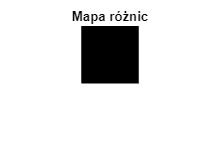

figure; imshow(D,[]); title('Mapa różnic');

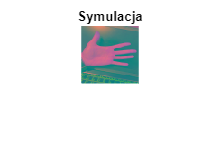

figure; imshow(simul_output,[]); title('Symulacja');

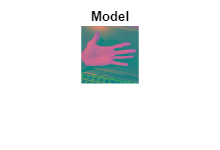

figure; imshow(I_model,[]); title('Model');